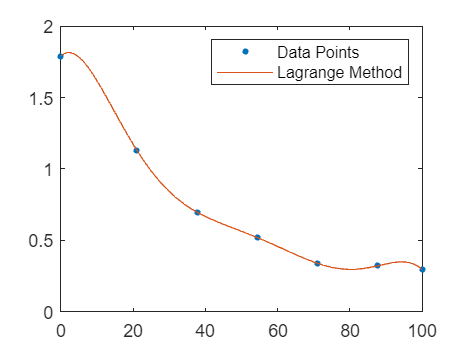

% Lagrange interpolation method
clf

T = [0 21.1 37.8 54.4 71.1 87.8 100];
mu = [1.79 1.13 0.696 0.519 0.338 0.321 0.296];

syms t;

Pl = @(t) 0;

for i = 1:length(mu)
    l = @(t) 1;

    for j = 1:length(mu)
        if (j ~= i)
            l = l * (t - T(j)) / (T(i) - T(j));
        end
    end

    Pl = Pl + l * mu(i);
end

plot(T, mu, '.', "MarkerSize", 10);
hold on

fplot(Pl, [T(1) T(length(mu))]);

legend(["Data Points", "Lagrange Method"])

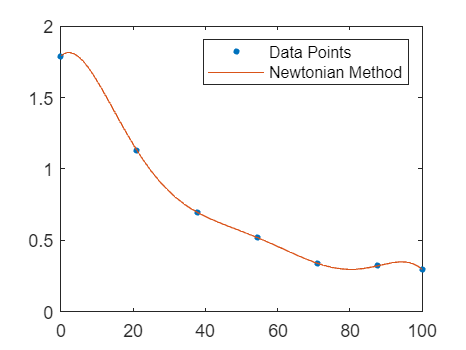

% Newton interpolation
clf

T = [0 21.1 37.8 54.4 71.1 87.8 100];
mu = [1.79 1.13 0.696 0.519 0.338 0.321 0.296];

syms t;

mus = [mu; zeros(1, length(mu)); zeros(1, length(mu)); zeros(1, length(mu)); zeros(1, length(mu)); zeros(1, length(mu)); zeros(1, length(mu))];

for j = 2:length(mu)
    for i = j:length(mu)
        mus(j, i) = (mus(j - 1, i) - mus(j - 1, j - 1)) / (T(i) - T(j - 1));
    end
end

Pn = @(t) mus(length(mu), length(mu));

for i = (length(mu) - 1):-1:1
    Pn = mus(i, i) + (t - T(i)) * Pn;
end

plot(T, mu, '.', "MarkerSize", 10);
hold on

fplot(Pn, [T(1) T(length(mu))]);

legend(["Data Points", "Newtonian Method"])

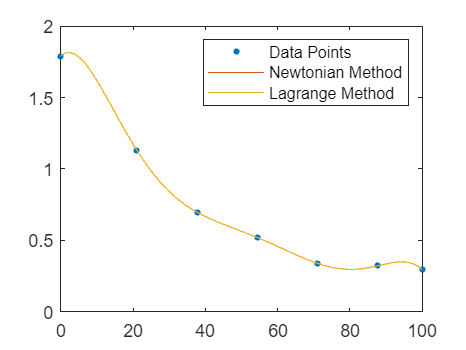

clf

plot(T, mu, '.', "MarkerSize", 10);
hold on

fplot(Pn, [T(1) T(length(mu))]);
fplot(Pl, [T(1) T(length(mu))]);

legend(["Data Points", "Newtonian Method", "Lagrange Method"])


Plagrange = matlabFunction(Pl);
Pnewton = matlabFunction(Pn);

fprintf("Lagrange for T = 10: %g", Plagrange(10));

Lagrange for T = 10: 1.62069

fprintf("Lagrange for T = 60: %g", Plagrange(60));

Lagrange for T = 60: 0.457169

fprintf("Newton for T = 10: %g", Pnewton(10));

Newton for T = 10: 1.62069

fprintf("Newton for T = 60: %g", Pnewton(60));

Newton for T = 60: 0.457169